% Clear previous data, close all figures, and reset command window
clear;
clc;
close all;

% 1. Create the optimization problem
% We're telling MATLAB: "We want to MAXIMIZE something."
% That "something" will be energy.
% hint: This MATLAB doc page will be helpful for understanding the
% Optimization Toolbox workflow:
%   https://www.mathworks.com/help/optim/ug/problem-based-workflow.html
prob = ?;

% 2. Define the optimization variables we can change in the problem
% These are the values MATLAB will try to optimize:
% - theta (tilt angle), must stay between 0 and 90 degrees
% - r (aspect ratio), must stay between 0.5 and 4
theta = ?;
r = ?;

% 3. Turn our energy function into an optimization problem MATLAB can work
% with.
% This step wraps our energy function so MATLAB can plug in different
% theta and r values while solving the problem.
% note: we're optimizing our energy function, so we should try to convert
% that function into an optimization expression
Eexpr = ?;

% 4. Tell MATLAB what we want to maximize
% We set our energy formula as the "objective" of the problem
% (this is what we want the solver to maximize)
prob.? = ?;

% 5. Give MATLAB a starting point to begin the search
% Optimization needs a guess to start from:
?;  % Start searching from a tilt angle of ? degrees
?;  % Start searching from an aspect ratio of ?

% Now solve the problem!
% hint: look for a Optimization Toolbox function meant to solve
% expressions. Store the outputs for plotting purposes later on!
?


Solving problem using fmincon.

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>



% Print the results to the screen
fprintf('Optimal Tilt Angle: %.2f deg\n', sol.theta);

Optimal Tilt Angle: 37.50 deg


fprintf('Optimal Aspect Ratio: %.2f\n', sol.r);

Optimal Aspect Ratio: 1.00


fprintf('Maximum Energy Output: %.2f units\n', fval);

Maximum Energy Output: 1965.93 units


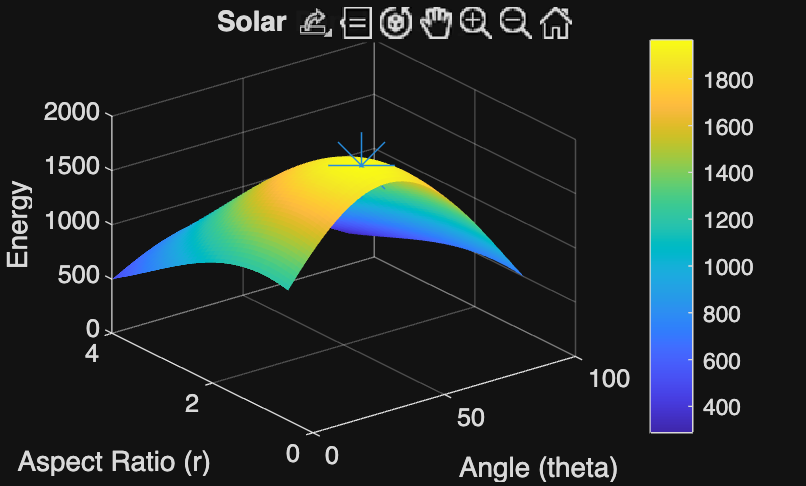



% 6. graph
% make a bunch of points for the x and y axis 
% the step for the angle is 1, the step for ratio is 0.1
% hint: keep theta and r within the bounds specified in task 3
[theta_grid, r_grid] = meshgrid(?, ?);

% now calculate the energy for every single point on the meshgrid
% hint: this is very similar to energyFcn, but we're applying it to the
% matrices we just created with meshgrid. You may consider using element-wise
% multiplication, see here:
% https://www.mathworks.com/help/matlab/ref/double.times.html
E_grid = ?;

% draw the 3d graph using the "surf" function
% hint: consider looking at the "EdgeColor" parameter if it doesn't turn
% out "pretty" :-)
surf(?, ?, ?);

% label everything using title, xlabel, ylabel, zlabel, and colorbar
?
?
?
?
?

% put a star on the plot to show where the most optimal point is
% hint: you will need a MATLAB plot function that lets you plot coordinates
% in 3-D space.
% hint: remember the outputs of the function used to solve the optimization
% problem!
?